# Dummy observations

- discussing all type of dummy observations

- setup, hyperparameters 

- analyzing the effect on the estimation



clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("SV.csv");

estimStart = datex.q(1971,2);
estimEnd = datex.q(2020,1);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);


## Sum of coefficients dummy


estimatorR1 = estimator.NormalWishart(meta);
estimatorR1.Settings

ans =   NormalWishart with properties:

             Sigma: "ar"
            Burnin: 0
         Exogenous: [3×1 logical]
    BlockExogenous: 0
    Autoregression: [3×1 double]
           Lambda1: 0.1000
           Lambda2: 0.5000
           Lambda3: 1
           Lambda4: [3×1 double]
           Lambda5: 1.0000e-03


estimatorR1.CanHaveDummies

ans = logical
   1



estimatorR2 = estimator.NormalWishart(meta);

estimatortmp = estimator.BetaTV(meta);
estimatortmp.CanHaveDummies

ans = logical
   0



sumCoeffD = dummies.SumCoefficients();
sumCoeffD.Lambda

ans = 1.0000e-04


modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , dummies={sumCoeffD} ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR1.initialize();
info1 = modelR1.presample(1000);


 Presampling model.ReducedForm (NormalWishart) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



betaMedian1 = calcMedian(modelR1,"beta");

rng(0)
modelR2.initialize();
info2 = modelR2.presample(1000);


 Presampling model.ReducedForm (NormalWishart) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



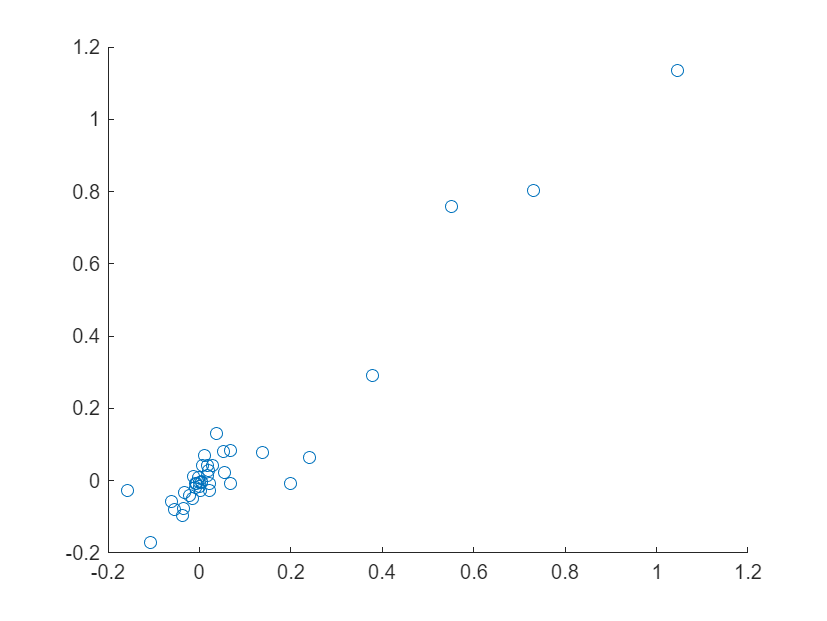

betaMedian2 = calcMedian(modelR2,"beta");

figure();scatter(betaMedian1, betaMedian2)

## Initial observation dummy

estimatorR3 = estimator.NormalWishart(meta);

initObsD = dummies.InitialObservations();
initObsD.Lambda


ans = 100000

modelR3 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR3 ...
    , dummies={initObsD} ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR3.initialize();
info3 = modelR3.presample(1000);
betaMedian3 = calcMedian(modelR3,"beta");


 Presampling model.ReducedForm (NormalWishart) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



figure();scatter(betaMedian1, betaMedian3)

## Long-run dummies

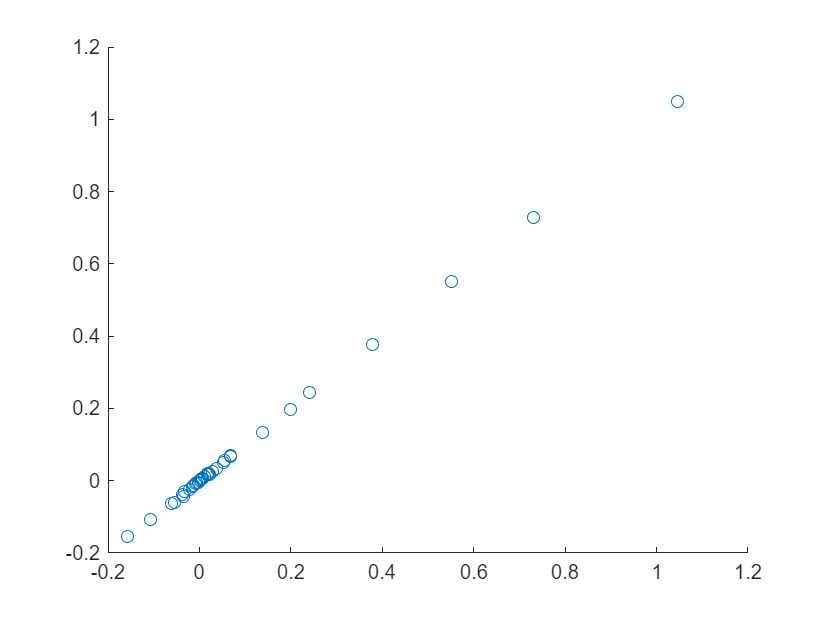

longRunTbx = tablex.forLongRunDummies(meta);

longRunTbx{"YER", "YER"} = 1;
longRunTbx{"HICSA", "HICSA"} = 1;
longRunTbx{"HICSA", "STN"} = 1;
longRunTbx{"STN", "HICSA"} = -1;
longRunTbx{"STN", "STN"} = 1;

longRunD = dummies.LongRun(Constraints=longRunTbx);
longRunD.Lambda
longRunD.Constraints

estimatorR4 = estimator.NormalWishart(meta);

ans = 1.0000e-04

ans =      1     0     0
     0     1     1
     0    -1     1


modelR4 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR4 ...
    , dummies={longRunD} ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR4.initialize();
info4 = modelR4.presample(1000);
betaMedian4 = calcMedian(modelR4,"beta");
figure();scatter(betaMedian1,betaMedian4)

## Minnesota dummies

- replicating prior = 51 in bear5


 Presampling model.ReducedForm (NormalWishart) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



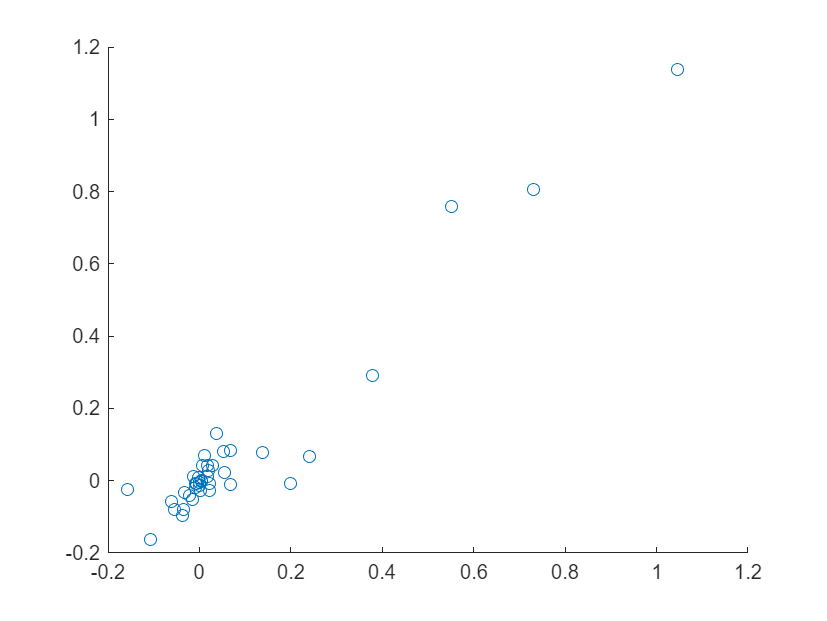

minnesotaD = dummies.Minnesota();
minnesotaD


estimatorR5 = estimator.Ordinary(meta);

modelR5 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...

minnesotaD =   Minnesota with properties:

             Lambda: 0.1000
           LagDecay: 1
    ExogenousLambda: 100
     Autoregression: 0.8000
          Exogenous: 0


    , estimator=estimatorR5 ...
    , dummies={minnesotaD} ...
    , stabilityThreshold=Inf ...
);

rng(0)
modelR5.initialize();
info5 = modelR5.presample(10000);

betaMedian5 = calcMedian(modelR5,"beta");



estimatorR6 = estimator.Minnesota(meta,Sigma="full");


 Presampling model.ReducedForm (Ordinary) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 



estimatorR6.Settings.Lambda1
estimatorR6.Settings.Lambda3
estimatorR6.Settings.Lambda4
estimatorR6.Settings.Autoregression
estimatorR6.Settings.Exogenous 

modelR6 = model.ReducedForm( ...

ans = 0.1000

    meta=meta ...

ans = 1

    , dataHolder=dataH ...

ans =    100
   100
   100


    , estimator=estimatorR6 ...

ans =     0.8000
    0.8000
    0.8000


    , stabilityThreshold=Inf ...

ans = 3×1 logical array
   0
   0
   0



 Presampling model.ReducedForm (Minnesota) [10000]
 ―――――――――――――――――――――――――――――――――――――――――――――――――◼  100% 



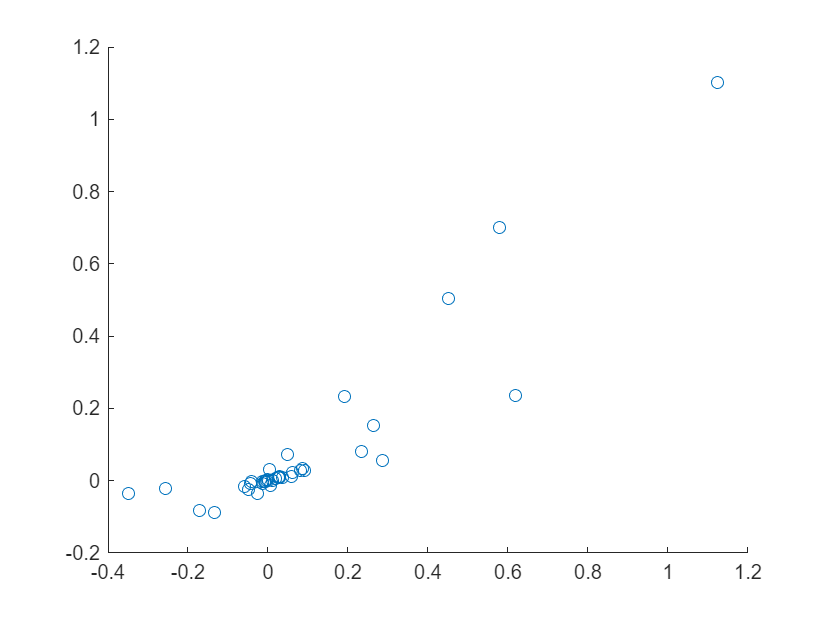

);

rng(0)
modelR6.initialize();
info6 = modelR6.presample(10000);

betaMedian6 = calcMedian(modelR6,"beta");

figure();scatter(betaMedian5, betaMedian6)